# Exercise 5

clear all; close all; clc;

## A

uc = 1080/2;
vc = 1920/2;
f = 1000;
K = [f, 0, uc;0,f,vc;0,0,1]

K =         1000           0         540
           0        1000         960
           0           0           1


s2 = sqrt(1/2);
R = [s2, -s2,0;s2,s2,0;0,0,1];
t = [0;0;10];
Proj = K*[R,t]

Proj = 	1.0e+03 *

    0.7071   -0.7071    0.5400    5.4000
    0.7071    0.7071    0.9600    9.6000
         0         0    0.0010    0.0100


% in solution pdf
%K = [100*s2,-100*s2,100,1000;100*s2,100*s2,200,2000;0,0,1,10]*pinv([R, t])
%Proj = [100*s2,-100*s2,100,1000;100*s2,100*s2,200,2000;0,0,1,10]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
Q = zeros(4, 8);
p = zeros(3, 8);
for i = 0:1
    for j = 0:1
        for k = 0:1
            idx = k+1+j*2+i*4;
            Q(:,idx) = [i;j;k;1];
            po = Proj*Q(:,idx);
            p(:,idx) = po/po(3);
        end
    end
end

## B

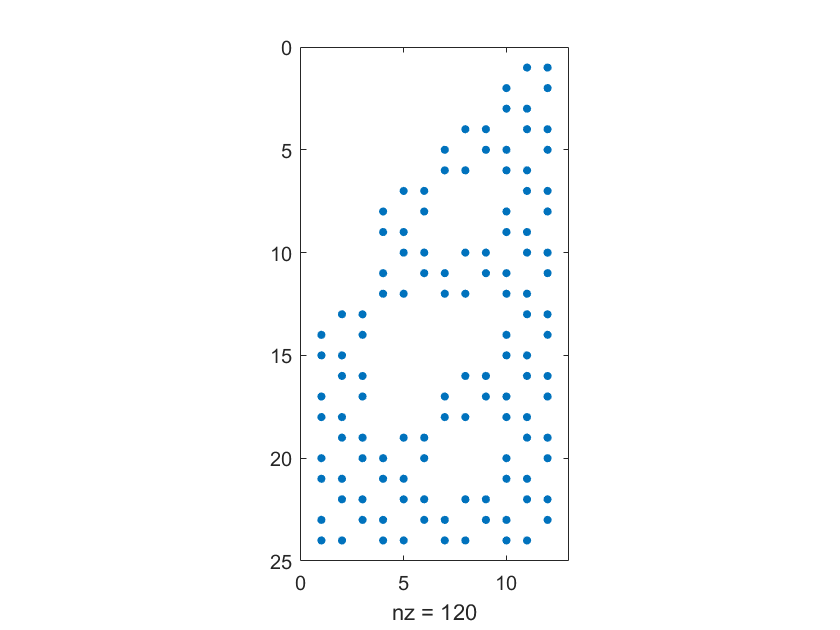

% DLT method
B = zeros(24,12);
for i = 1:8
    X = Q(1,i);
    Y = Q(2,i);
    Z = Q(3,i);
    x = p(1,i);
    y = p(2,i);
    B((i-1)*3+1:i*3,:) = [0, -X, X*y, 0, -Y, Y*y, 0, -Z, Z*y, 0, -1, y;
        X, 0, -X*x, Y, 0, -Y*x, Z, 0, -Z*x, 1, 0, -x;
        -X*y, X*x, 0, -Y*y, Y*x, 0, -Z*y, Z*x, 0, -y, x, 0
        ];
end
spy(B)

[~,~,V] = svd(B);
P = V(:,end);
P = [P(1),P(4),P(7),P(10);P(2),P(5),P(8),P(11);P(3),P(6),P(9),P(12)]

P =     0.0634   -0.0634    0.0484    0.4839
    0.0634    0.0634    0.0860    0.8603
    0.0000    0.0000    0.0001    0.0009


error = zeros(8,1);
for i = 1:8
    po = P*Q(:,i);
    po = po/po(3);
    e = po-p(:,i);
    error(i) = e'*e;
end
error

error = 	1.0e+-19 *

    0.1921
    0.0008
    0.0092
    0.0861
    0.1128
    0.0091
    0.0003
    0.1804


sum(error)

ans = 5.9087e-20

T1 = normal2(p)

T1 =     0.0209         0  -11.2887
         0    0.0209  -21.4798
         0         0    1.0000


T2 = normal3(Q)

Qm =      0     0     0     1


ans = 3

T2 =      2     0     0    -1
     0     2     0    -1
     0     0     2    -1
     0     0     0     1


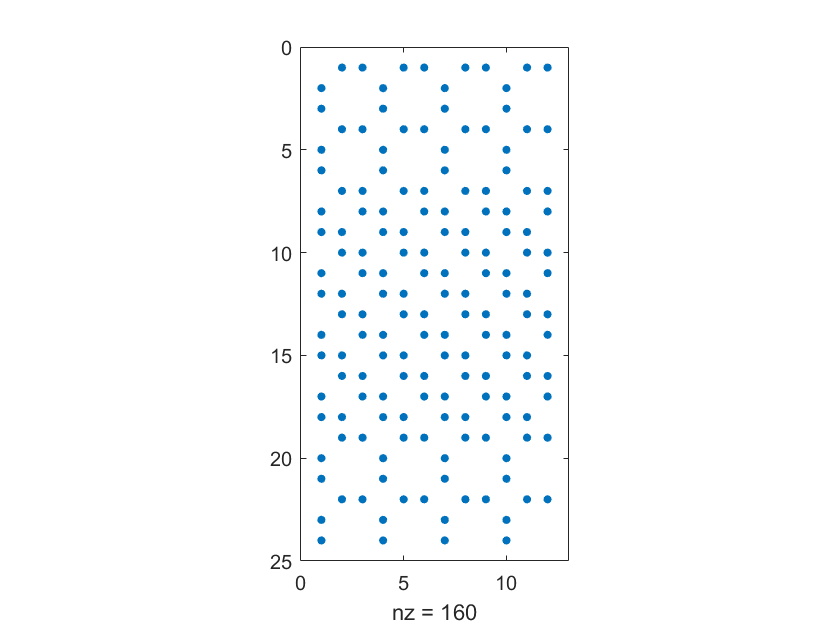

p1 = T1*p;
Q1 = T2*Q;
% DLT method
B = zeros(24,12);
for i = 1:8
    X = Q1(1,i);
    Y = Q1(2,i);
    Z = Q1(3,i);
    x = p1(1,i);
    y = p1(2,i);
    B((i-1)*3+1:i*3,:) = [0, -X, X*y, 0, -Y, Y*y, 0, -Z, Z*y, 0, -1, y;
        X, 0, -X*x, Y, 0, -Y*x, Z, 0, -Z*x, 1, 0, -x;
        -X*y, X*x, 0, -Y*y, Y*x, 0, -Z*y, Z*x, 0, -y, x, 0
        ];
end
spy(B)

[~,~,V] = svd(B);
P = V(:,end);
P = [P(1),P(4),P(7),P(10);P(2),P(5),P(8),P(11);P(3),P(6),P(9),P(12)];
P = pinv(T1)*P*T2

P =   -38.9539   38.9539  -29.7482 -297.4816
  -38.9539  -38.9539  -52.8856 -528.8562
   -0.0000    0.0000   -0.0551   -0.5509


error = zeros(8,1);
for i = 1:8
    po = P*Q(:,i);
    po = po/po(3);
    e = po-p(:,i);
    error(i) = e'*e;
end
error

error = 	1.0e+-20 *

    0.1467
    0.1475
    0.4494
    0.3444
    0.4518
    0.4103
    0.2140
    0.1598


sum(error)

ans = 2.3237e-20

% We can find that the error decrease because of normalization

## C

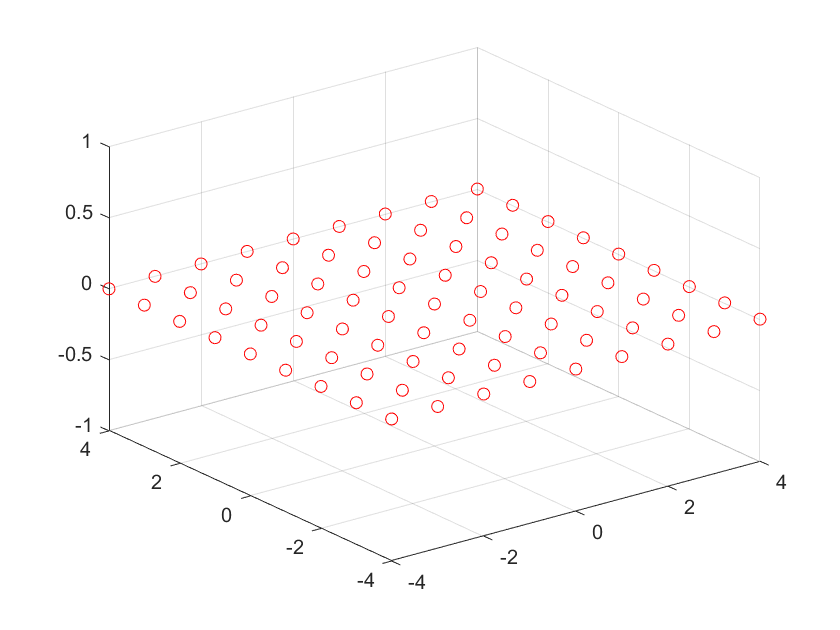

% Checkboard calibration
Q = checkerboard_points(9, 9, 1);
figure;
for i = 1:9
    for j = 1:9
        scatter3(Q(1,i,j), Q(2,i,j), Q(3,i,j),'red');
        hold on;
    end
end
hold off;

## D

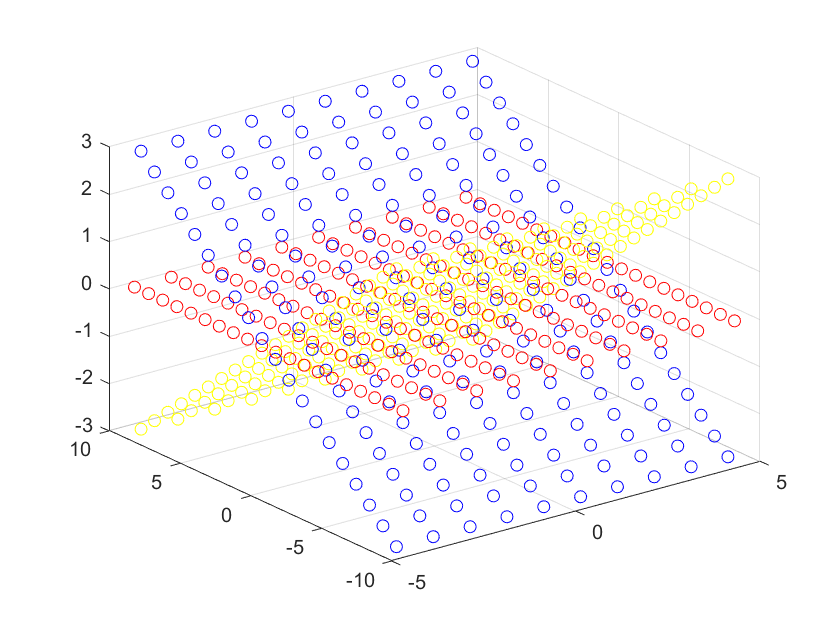

N = 10;
M = 20;
l = 1;
Q = checkerboard_points(N, M, l);
Qa = Q;
Qb = Q;
Qc = Q;
Ra = rot(pi/10, 0, 0);
Rb = rot(0, 0, 0);
Rc = rot(-pi/10, 0, 0);
figure;
for i = 1:N
    for j = 1:M
        q = Q(:,i,j);
        q = reshape(q,3,1);
        qa = Ra*q;
        qb = Rb*q;
        qc = Rc*q;
        Qa(:,i,j) = qa;
        Qb(:,i,j) = qb;
        Qc(:,i,j) = qc;
        scatter3(qa(1), qa(2), qa(3),'blue');
        hold on;
        scatter3(qb(1), qb(2), qb(3),'red');
        hold on;
        scatter3(qc(1), qc(2), qc(3),'yellow');
        hold on;
    end
end
set(gca, 'ylim', [-10,10], 'zlim',[-3,3])
hold off;

% Projection
qa = project(Qa, Proj);
qb = project(Qb, Proj);
qc = project(Qc, Proj);

## E

Q = reshape(Qb, 3, 200);
Q(3,:) = 1;
%qa1 = qa;
qa = reshape(qa, 3, 200);
qb = reshape(qb, 3, 200);
qc = reshape(qc, 3, 200);

H1 = estimateHomography(qa, Q)

H1 =     3.3375   -2.3865   25.4874
    3.3375    4.5743   45.3109
    0.0000    0.0015    0.0472


e1 = H1*Q;
for i = 1:200
    e1(:,i) = e1(:,i)/e1(3,i);
end
e1 = qa-e1;
e1 = sqrt(e1(1,:).^2+e1(2,:).^2);
mean(e1)

ans = 5.1001e-10

H2 = estimateHomography(qb, Q)

H2 =     3.2821   -3.2821   25.0646
    3.2821    3.2821   44.5593
    0.0000   -0.0000    0.0464


e2 = H2*Q;
for i = 1:200
    e2(:,i) = e2(:,i)/e2(3,i);
end
e2 = qb-e2;
e2 = sqrt(e2(1,:).^2+e2(2,:).^2);
mean(e2)

ans = 5.6676e-10

H3 = estimateHomography(qc, Q)

H3 =     3.3375   -3.9617   25.4874
    3.3375    1.7739   45.3109
    0.0000   -0.0015    0.0472


e3 = H3*Q;
for i = 1:200
    e3(:,i) = e3(:,i)/e3(3,i);
end
e3 = qc-e3;
e3 = sqrt(e3(1,:).^2+e3(2,:).^2);
mean(e3)

ans = 5.6521e-10

## F

H = [H1;H2;H3];
K = estimateIntrinsics(H)

K = 	1.0e+03 *

    1.0000    0.0000    0.5400
         0    1.0000    0.9600
         0         0    0.0010


## G

[Rs, Ts] = estimateExtrinsics(K, H)

Rs =     0.7071   -0.6725    0.2185
    0.7071    0.6725   -0.2185
    0.0000    0.3090    0.9511
    0.7071   -0.7071   -0.0000
    0.7071    0.7071    0.0000
    0.0000   -0.0000    1.0000
    0.7071   -0.6725   -0.2185
    0.7071    0.6725    0.2185
    0.0000   -0.3090    0.9511


Ts =    -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000
    0.0472    0.0464    0.0472


% Integrate in a function
q = [qa;qb;qc];
[K, Rs, Ts] = calibrateCamera(q ,Q)

K = 	1.0e+03 *

    1.0000    0.0000    0.5400
         0    1.0000    0.9600
         0         0    0.0010


Rs =     0.7071   -0.6725    0.2185
    0.7071    0.6725   -0.2185
    0.0000    0.3090    0.9511
    0.7071   -0.7071   -0.0000
    0.7071    0.7071    0.0000
    0.0000   -0.0000    1.0000
    0.7071   -0.6725   -0.2185
    0.7071    0.6725    0.2185
    0.0000   -0.3090    0.9511


Ts =    -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000
    0.0472    0.0464    0.0472


Proj = K*[R(1:3, 1:3),t(:,1)]

Proj = 	1.0e+03 *

    0.7071   -0.7071    0.5400    5.4000
    0.7071    0.7071    0.9600    9.6000
         0         0    0.0010    0.0100
